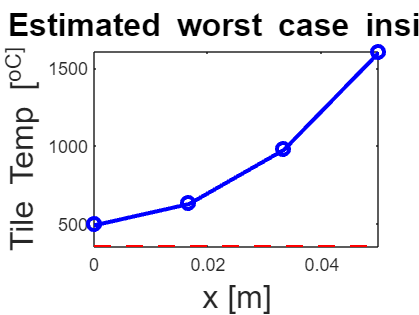

clear all
L1=0.05;L2=0.1;
F1=tile_prof(L1);

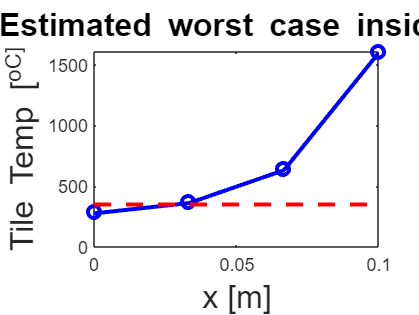

F2=tile_prof(L2);

    0.0500    0.0750

    0.0625    0.0750

    0.0688    0.0750

    0.0688    0.0719

    0.0688    0.0703

    0.0695    0.0703

    0.0699    0.0703

    0.0699    0.0701

    0.0700    0.0701

    0.0701    0.0701



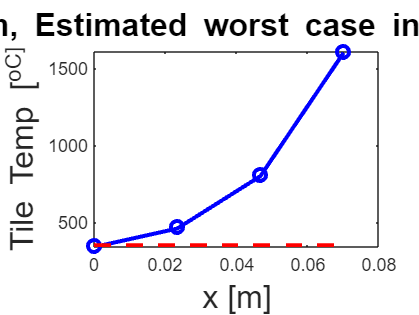

e1=0.1; e2=1e-4;
while (abs(F1)>e1 || abs(L1-L2)>e2)
    L0=(L1+L2)/2; F0=tile_prof(L0);
    if F1*F0 > 0
        L1 = L0; F1=F0;
    else
        L2 = L0; F2 = F0;
    end
    disp([L1 L2])
end

disp(['Min thickness: ',num2str(L0,4),'[m]'])

Min thickness: 0.07007[m]


function [T_error] = tile_prof(L)
dx=L/3; dt=1;alfa=0.015*3600/(800*150);
gam=alfa*dt/dx^2;beta=10;Ta=300;
tp=[300 300 300]';
A = [2*dx*beta+3 -4 1; -gam 1+2*gam -gam; 0 -gam 1+2*gam];
b = [2*dx*beta*Ta tp(2) tp(3)+1600*gam]';
tp = inv(A)*b;
T_0_1 = tp(1);
dx=L/3; dt=0.5;gam=alfa*dt/dx^2;
tp=[300 300 300]';t_data=[tp' 1600];
A=[2*dx*beta+3 -4 1; -gam 1+2*gam -gam; 0 -gam 1+2*gam];
for k2=1:2
    b=[2*dx*beta*Ta tp(2) tp(3)+1600*gam]';
    tp = inv(A)*b;
    t_data=[t_data;[tp' 1600]];
end
Error=abs(tp(1)-T_0_1);
T_0_05=tp(1);
T_error=350-T_0_05-Error;
L_data=[0 L/3 2*L/3 L];
plot(L_data,t_data(3,:)+Error,'ob',L_data,t_data(3,:),'b',[0 L],[350 350], ...
    '--r','LineWidth',2)
xlabel('x [m]','FontSize',16)
ylabel('Tile Temp [^oC]','FontSize',16)
title(['L=',num2str(L,4),' m, Estimated worst case inside = ', ...
    num2str(T_0_05+Error,5),'^oC'],'FontSize',16)
drawnow
end